### DPS 7600: Assignment 1

### Prepared By: Andrew Stone (201534971)

### Prepared For: Dr. Sarah Power

#### **Question 1:**

System A: $y\left\lbrack n\right\rbrack -y\left\lbrack n-1\right\rbrack +y\left\lbrack n-2\right\rbrack =x\left\lbrack n\right\rbrack$

a) compute by hand the systems impulse response $h_{A\left\lbrack n\right\rbrack }$ directly from the difference equation for a sufficient interval of ***n*** to capture the behaviour of all ***n.***

	Causal system ∴ y[n] = 0 until non-zero input...

	
$$y\left\lbrack -5\right\rbrack \;\textrm{to}\;y\left\lbrack -1\right\rbrack =0$$


	
$$\begin{array}{l}
y\left\lbrack 0\right\rbrack =x\left\lbrack 0\right\rbrack +y\left\lbrack \left(0\right)-1\right\rbrack -y\left\lbrack \left(0\right)-2\right\rbrack =x\left\lbrack 0\right\rbrack +y\left\lbrack -1\right\rbrack -y\left\lbrack -2\right\rbrack =1+0-0=1\\
y\left\lbrack 1\right\rbrack =x\left\lbrack 1\right\rbrack +y\left\lbrack \left(1\right)-1\right\rbrack -y\left\lbrack \left(1\right)-2\right\rbrack =x\left\lbrack 1\right\rbrack +y\left\lbrack 0\right\rbrack -y\left\lbrack -1\right\rbrack =0+1-0=1\\
y\left\lbrack 2\right\rbrack =x\left\lbrack 2\right\rbrack +y\left\lbrack \left(2\right)-1\right\rbrack -y\left\lbrack \left(2\right)-2\right\rbrack =x\left\lbrack 2\right\rbrack +y\left\lbrack 1\right\rbrack -y\left\lbrack 0\right\rbrack =0+1-1=0\\
y\left\lbrack 3\right\rbrack =x\left\lbrack 3\right\rbrack +y\left\lbrack \left(3\right)-1\right\rbrack -y\left\lbrack \left(3\right)-2\right\rbrack =x\left\lbrack 3\right\rbrack +y\left\lbrack 2\right\rbrack -y\left\lbrack 1\right\rbrack =0+0-1=-1\\
y\left\lbrack 4\right\rbrack =x\left\lbrack 4\right\rbrack +y\left\lbrack \left(4\right)-1\right\rbrack -y\left\lbrack \left(4\right)-2\right\rbrack =x\left\lbrack 4\right\rbrack +y\left\lbrack 3\right\rbrack -y\left\lbrack 2\right\rbrack =0+\left(-1\right)-0=-1\\
y\left\lbrack 5\right\rbrack =x\left\lbrack 5\right\rbrack +y\left\lbrack \left(5\right)-1\right\rbrack -y\left\lbrack \left(5\right)-2\right\rbrack =x\left\lbrack 5\right\rbrack +y\left\lbrack 4\right\rbrack -y\left\lbrack 3\right\rbrack =0+\left(-1\right)-\left(-1\right)=0\\
y\left\lbrack 6\right\rbrack =x\left\lbrack 6\right\rbrack +y\left\lbrack \left(6\right)-1\right\rbrack -y\left\lbrack \left(6\right)-2\right\rbrack =x\left\lbrack 6\right\rbrack +y\left\lbrack 5\right\rbrack -y\left\lbrack 4\right\rbrack =0+1-0=1\\
y\left\lbrack 7\right\rbrack =x\left\lbrack 7\right\rbrack +y\left\lbrack \left(7\right)-1\right\rbrack -y\left\lbrack \left(7\right)-2\right\rbrack =x\left\lbrack 7\right\rbrack +y\left\lbrack 6\right\rbrack -y\left\lbrack 5\right\rbrack =0+1-0=1
\end{array}$$


	Patten is 1,1,0,-1,-1... for n ≥ 0

b) compute impulse response function $h_{A\left\lbrack n\right\rbrack }$ directly from diffrence equation.

plot $h_{A\left\lbrack n\right\rbrack }$ for -5 ≤ n ≤ 60.

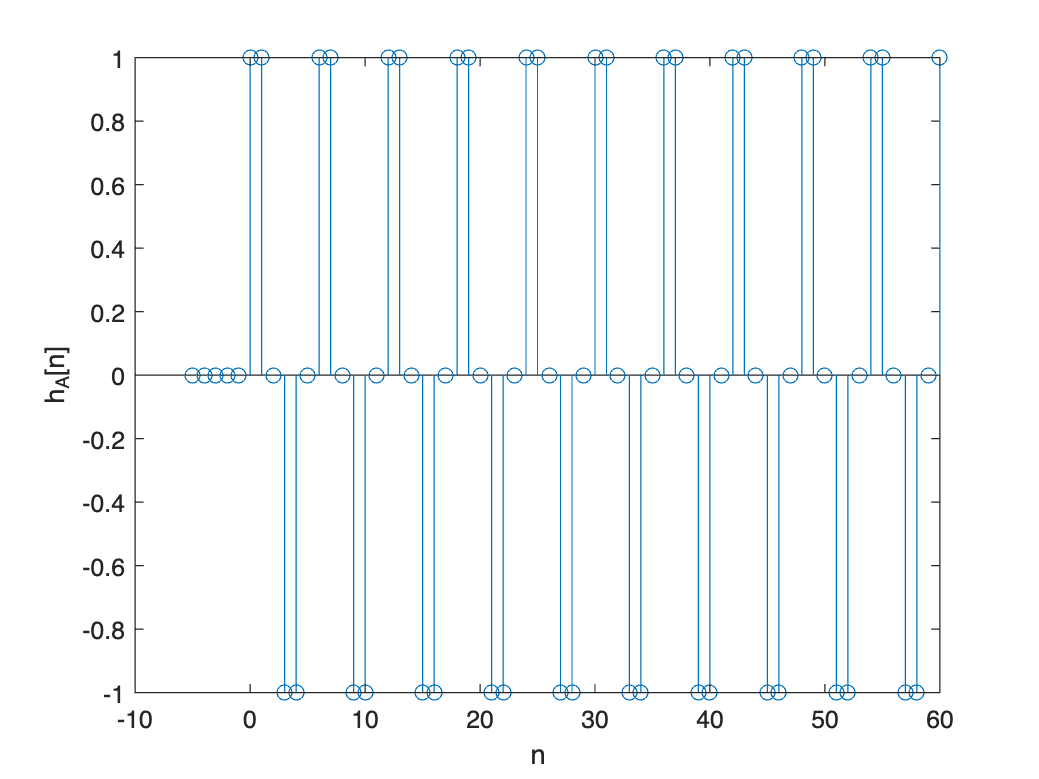

L = 60-(-5)+1;
 
impulse = zeros(L,1);
h_a = zeros(L,1);
n = -5:60;
impulse(0+6) = 1;
 
for i = -5:60
    if i-2+6 > 1
        h_a(i+6) = impulse(i+6)+h_a(i-1+6)-h_a(i-2+6);
    elseif i-1+6 > 1
        h_a(i+6) = impulse(i+6)+h_a(i-1+6);
    else
        h_a(i+6) = impulse(i+6);
    end
end
 
f1 = figure("Name","Question 1b) Impulse response of System A");
stem(n, h_a);
xlabel('n');
ylabel('{h_A[n]}');

c) use "*filter"* matlab function to determine system's inpluse response $h_A \left\lbrack n\right\rbrack$ using coefficients of the differenec equation. Plot for -5 ≤ n ≤ 60.

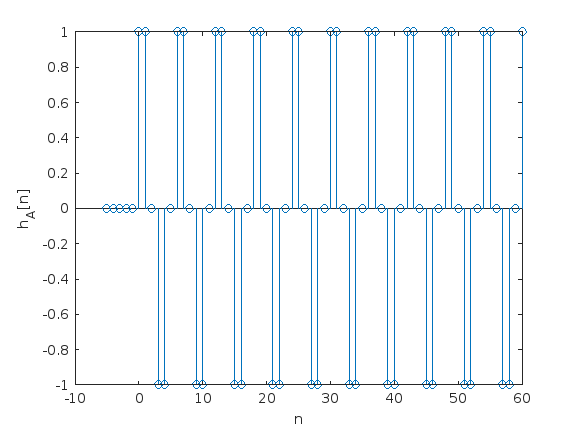

L = 60-(-5)+1;
b = 1;
coeff = [1 -1 1];
 
impulse = zeros(1,L);
n = -5:60;
impulse(0+6) = 1;

% h_a = zeros(1,L);
h_a = filter(b,coeff,impulse);

f2 = figure("Name","Question 1c) Impulse Response of System A using Filter function");
stem(n, h_a);
xlabel('n');
ylabel('{h_A[n]}');

d) Is the length of $h_A \left\lbrack n\right\rbrack$what I expected based on the difference equation?

e) Use filter function to determine system's response to input x[n] below.

Plot ***x[n] vs. n ***and ***y[n] vs. n ***for ***-5 ≤ n ≤ 60 ***in the same figure using the subplot commmand.

	
$$x\left\lbrack n\right\rbrack =\cos \left(\frac{2\pi }{6}n\;\right)u\left\lbrack n\right\rbrack$$


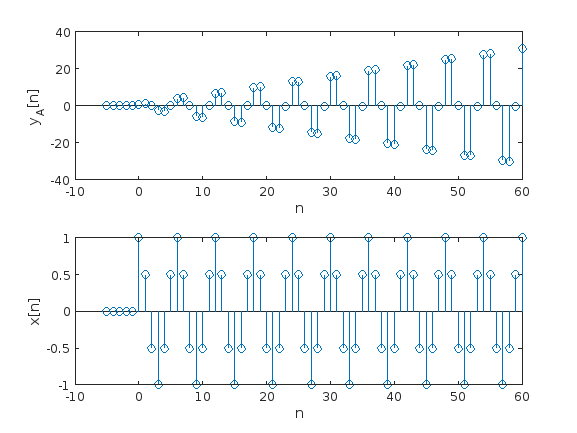

L = 60-(-5)+1;
b = 1;
a = [1 -1 1];
u = zeros(1, L);
x = zeros(1, L);
for i = -5:60
   if i < 0
       u(i+6) = 0;
   else
       u(i+6) = 1;
   end
end
 
for i = -5:60
   x(i+6) = cos(2*pi()/6*i)*u(i+6);
end
 
n = -5:60;

% y = zeros(1,L); 
y = filter(b,a,x);
 
f3 = figure("Name","Question 1e) {x[n]=cos(2\pi/6)u[n]} using filter function");
subplot(2,1,1);%,"Name"," Q1e) System A Response to {x[n]=cos(2\pi/6)u[n]}");
stem(n, y);
xlabel('n');
ylabel('{y_A[n]}');
 
subplot(2,1,2);%, "Name","Q1e) {x[n]=cos(2\pi/6)u[n]}");
stem(n, x);
xlabel('n');
ylabel('{x[n]}');

f) Is the system stable? Justify answer using y[n] and only using $h_A \left\lbrack n\right\rbrack$.

	Visually inspecting y[n] in the above plot, the system does not appear stable due to the growning output without showing any indicaiton of being bound as $n\to \infty$.

	$h_A \left\lbrack n\right\rbrack$is defined by $y\left\lbrack n\right\rbrack -y\left\lbrack n-1\right\rbrack +y\left\lbrack n-2\right\rbrack =x\left\lbrack n\right\rbrack \Rightarrow y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack$

Because output y[n] depend on past instance of y[n] i.e. the terms y[n-1] and y[n-2], there is reason to suspect that the output will grown unbounded as $n\to \infty$.

#### **Question 2:**

	System B: $h_B \left\lbrack n\right\rbrack =h_A \left\lbrack n\right\rbrack \left(u\left\lbrack n\right\rbrack -u\left\lbrack n-5\right\rbrack \right)$

a) compute $h_B \left\lbrack n\right\rbrack$ for -5 ≤ n ≤ 60.

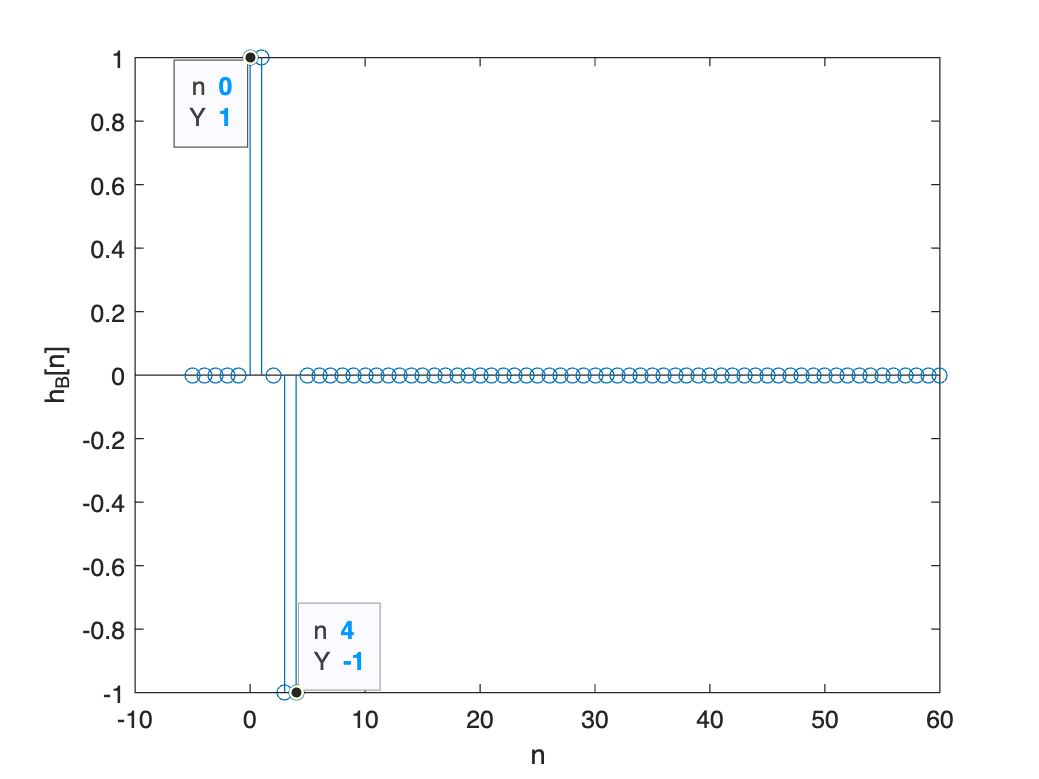

L = 60-(-5)+1;
 
impulse = zeros(L,1);
h_a = zeros(L,1);
h_b = zeros(L,1);
n = -5:60;
impulse(0+6) = 1;
 
u = zeros(1, L);
 
for i = -5:60
   if i < 0
       u(i+6) = 0;
   else
       u(i+6) = 1;
   end
end
 
for i = -5:60
    if i-2+6 > 1
        h_a(i+6) = impulse(i+6)+h_a(i-1+6)-h_a(i-2+6);
    elseif i-1+6 > 1
        h_a(i+6) = impulse(i+6)+h_a(i-1+6);
    else
        h_a(i+6) = impulse(i+6);
    end
end
 
for i = -5:60
    if i-5 < 0
        h_b(i+6) = h_a(i+6)*u(i+6);
    else
        h_b(i+6) = h_a(i+6)*(u(i-5+6) - u(i+6));       
    end
end
  
f4 = figure("Name","Question 2a: Impulse Response of System B");
stem(n, h_b)
xlabel('n')
ylabel('{h_B[n]}')

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,4,-1);
datatip(chart2,0,1);

dt = findobj(gca,"DataIndex",6);
set(dt,"Location","southwest");

ax4 = gca;
chart4 = ax4.Children(1);
chart4.DataTipTemplate.DataTipRows(1).Label="n";

b) Since this is an FIR system, the linear constant coefficient difference equation can be found directly from the convolution sum. Find (by hand) the difference equation for System B.

	Transform $h_B \left\lbrack n\right\rbrack$to series of impluses: $h_B \left\lbrack n\right\rbrack =\delta \;\left\lbrack n\right\rbrack +\delta \;\left\lbrack n-1\right\rbrack -\delta \;\left\lbrack n-3\right\rbrack -\delta \;\left\lbrack n-4\right\rbrack$

	
$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h_B \left\lbrack n\right\rbrack \\
=\sum_{k-\infty }^{\infty } x\left\lbrack n-k\right\rbrack \left(\delta \;\left\lbrack k\right\rbrack +\delta \;\left\lbrack k-1\right\rbrack -\delta \;\left\lbrack k-3\right\rbrack -\delta \;\left\lbrack k-4\right\rbrack \right)\\
=\sum_{k-\infty }^{\infty } x\left\lbrack n-k\right\rbrack \delta \;\left\lbrack k\right\rbrack +\sum_{k-\infty }^{\infty } x\left\lbrack n-k\right\rbrack \delta \;\left\lbrack k-1\right\rbrack -\sum_{k-\infty }^{\infty } x\left\lbrack n-k\right\rbrack \delta \;\left\lbrack k-3\right\rbrack -\sum_{k-\infty }^{\infty } x\left\lbrack n-k\right\rbrack \delta \;\left\lbrack k-4\right\rbrack \\
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack -x\left\lbrack n-3\right\rbrack -x\left\lbrack n-4\right\rbrack \;\left(\textrm{via}\;\textrm{sifting}\;\textrm{property}\right)
\end{array}$$


c) Using filter funciton & coefficients from the difference equation, determine system's response to input x[n] (shown below). Plot x[n] and y[n] for -5 ≤ n ≤ 60 in same figure using subplot.

	
$$x\left\lbrack n\right\rbrack =\cos \left(\frac{2\pi }{6}n\;\right)u\left\lbrack n\right\rbrack$$


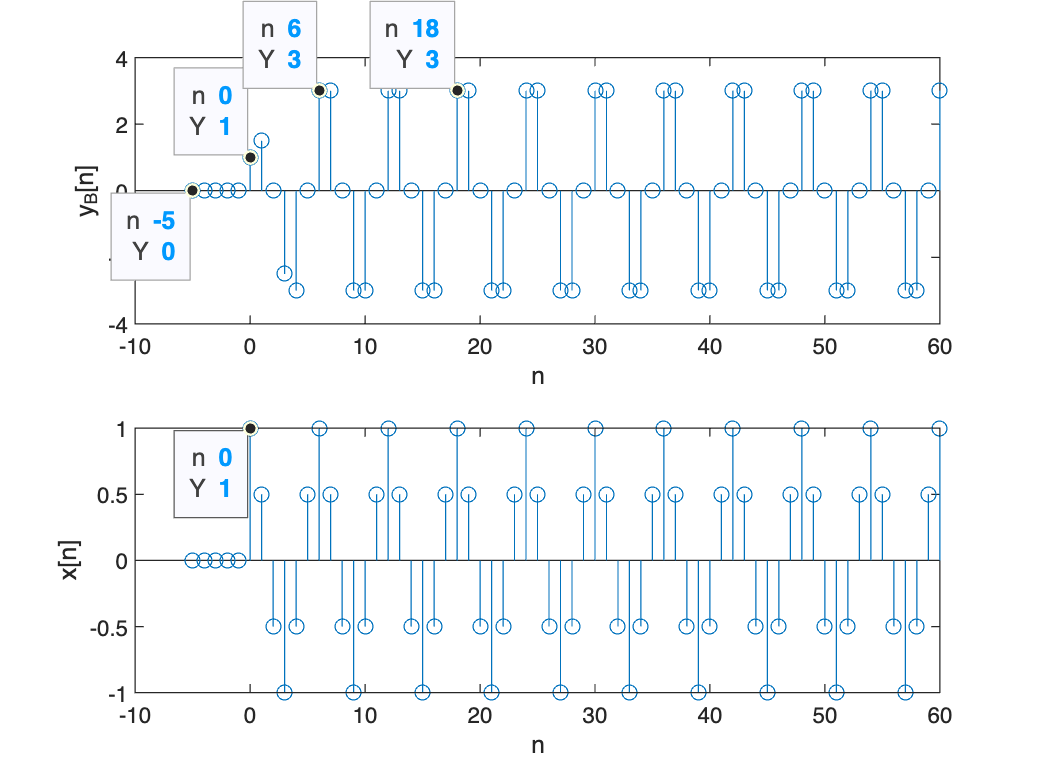

L = 60-(-5)+1;
b = [1 1 0 -1 -1];
a = 1;
u = zeros(1, L);
x = zeros(1, L);

for i = -5:60
   if i < 0
       u(i+6) = 0;
   else
       u(i+6) = 1;
   end
end
 
for i = -5:60
   x(i+6) = cos(2*pi()/6*i)*u(i+6);
end
 
n = -5:60;
 
y_b = filter(b,a,x);
 
f5 = figure("Name","Question 2c: response of System B w.r.t {x[n]=cos(2\pi/6)u[n]}");
subplot(2,1,1);
stem(n, y_b);
xlabel('n');
ylabel('{y_B[n]}');

subplot(2,1,2);
stem(n, x);
xlabel('n');
ylabel('{x[n]}');

subplot(2,1,1)
ax = gca;
chart = ax.Children(1);
datatip(chart,0,1,"Location","northwest");
datatip(chart,-5,0,"Location","southwest");
datatip(chart,6,3,"Location","northwest");
datatip(chart,18,3,"Location","northwest");

subplot(2,1,2)
ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,0,1,"Location","southwest");

subplot(2,1,1)
ax5 = gca;
chart5 = ax5.Children(1);
chart5.DataTipTemplate.DataTipRows(1).Label="n";
subplot(2,1,2)
ax5 = gca;
chart5 = ax5.Children(1);
chart5.DataTipTemplate.DataTipRows(1).Label="n";

d) Is the system stable? Justify your answer.

	By visual inspection of plot $y_B \left\lbrack n\right\rbrack$above we can see that for n ≥ 4 the output does not grown beyond |1| i.e. $y_B \left\lbrack n\right\rbrack$is bound between [-1,1].

	By examining the difference equation we see that:

	
$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack -x\left\lbrack n-3\right\rbrack -x\left\lbrack n-4\right\rbrack \;\left(\textrm{via}\;\textrm{sifting}\;\textrm{property}\right)$$


Because the output is the result of a summable input, we can suspect that the output shouldn't grown unbound since the result of x[n] is bound for all n.

e) Determine the response of System B to input x[n] (shown above) through convolution using ***conv*** function. Plot x[n] & y[n] for 0 ≤ n ≤ 60. Compare the result to those obtained in part c).

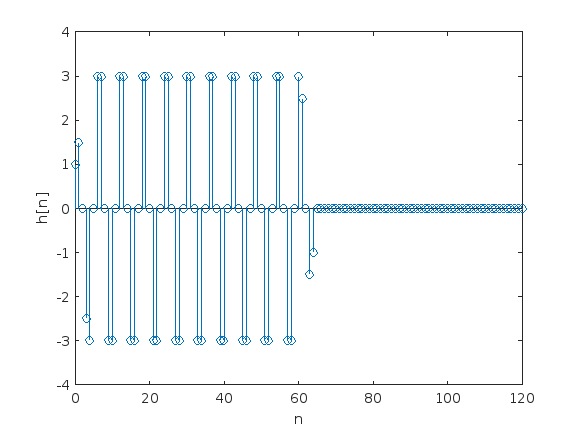

L = 60-(-5)+1;
 
impulse = zeros(L,1);
h_a = zeros(L,1);
h_b = zeros(L,1);
x = zeros(L,1);

impulse(0+6) = 1;

u = zeros(1, L);

for i = -5:60
	if i < 0
		u(i+6) = 0;
		x(i+6) = 0;
	else
		u(i+6) = 1;
		x(i+6) = cos(2*pi/6*i);
	end
end
 
for i = -5:60
	if i-2+6 > 1
		h_a(i+6) = impulse(i+6)+h_a(i-1+6)-h_a(i-2+6);
	elseif i-1+6 > 1
		h_a(i+6) = impulse(i+6)+h_a(i-1+6);
	else
		h_a(i+6) = impulse(i+6);
	end
end

for i = -5:60
	if i-5 < 0
		h_b(i+6) = h_a(i+6)*u(i+6);
	else
		h_b(i+6) = h_a(i+6)*(u(i-5+6) - u(i+6));
	end
end

h_b_trim = h_b(0+6:L);
x_trim = x(0+6:L);

n = 0:size(x_trim)+size(h_b_trim)-1-1;

y_b = conv(x_trim, h_b_trim);

f6 = figure("Name","Question 2e: Impulse Response of {x[n]=cos(2\pi/6)u[n]} using conv()");
stem(n, y_b);
xlabel('n');
ylabel('h[n]');

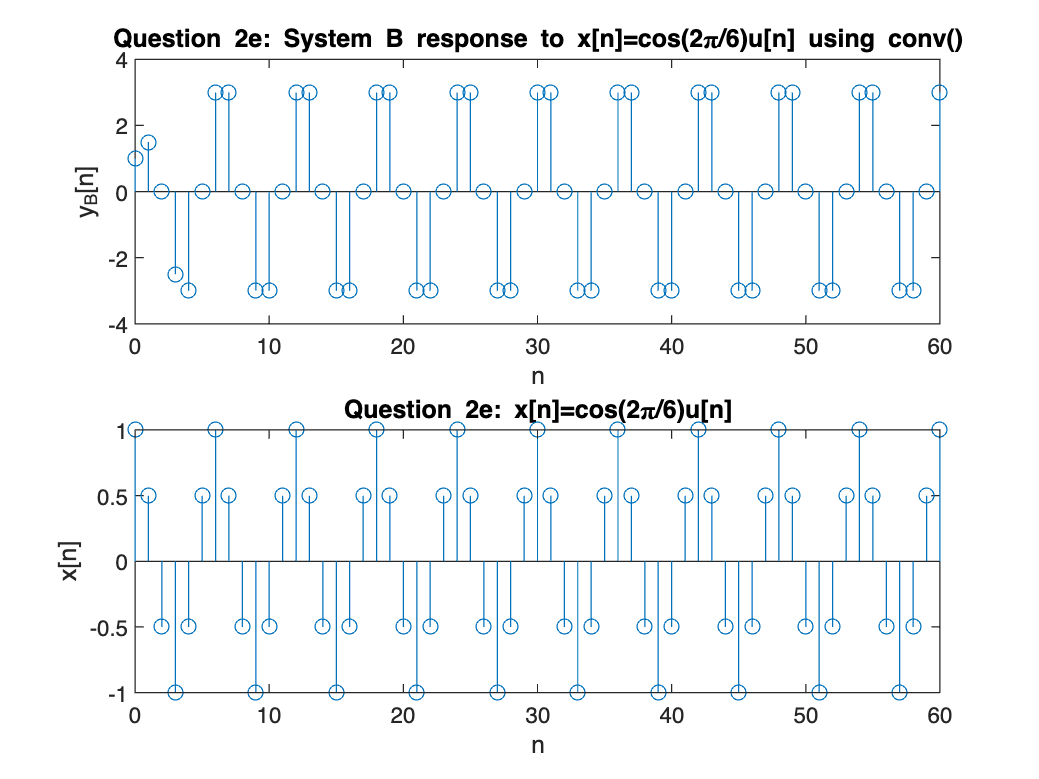

y_b = y_b(1:61);
x = x(0+6:L);
n = 0:60;

subplot(2,1,1);
stem(n,y_b)
xlabel('n');
ylabel('{y_B[n]}')
title('Question 2e: System B response to {x[n]=cos(2\pi/6)u[n]} using conv()');
 
subplot(2,1,2); 
stem(n,x)
xlabel('n');
ylabel('{x[n]}')
title('Question 2e: {x[n]=cos(2\pi/6)u[n]}');

comment(s):

	Result obtained from convolution sun using conv() function is the same result obtained in part c).

	If n [-5,-1] interval were included for both signals, there would be a 9 step delay on the output. This is a result of the output being "padded" with 0's at the beginning of the two arrays because conv() function does not allow you to provide negative values to conv().

f) What is the total length of output y[n] in part e)? why is it this length?

	The total length after trimming negative time from the arrays is the sum of the lengths of the two (trimmed) convolved signals minus 1 (61 + 61 - 1) = 121 length. This is because of the "flip-shift-slide" action involved in convolution. We have two function both with length 61 (i.e. 0 to 60). One of these functions is flipped about n=0, the "shift to infinity" doesn't afftect the length of the output array but the "sliding" does. This is due to the function that has been flipped & shifted, convolution is computed for all values of n for of the flipped & shifted function for all it's values as it enters AND leaving the overlapping range of the function it is convolved with, effectively doubling data points of the resulting output.

#### **Question 3:**

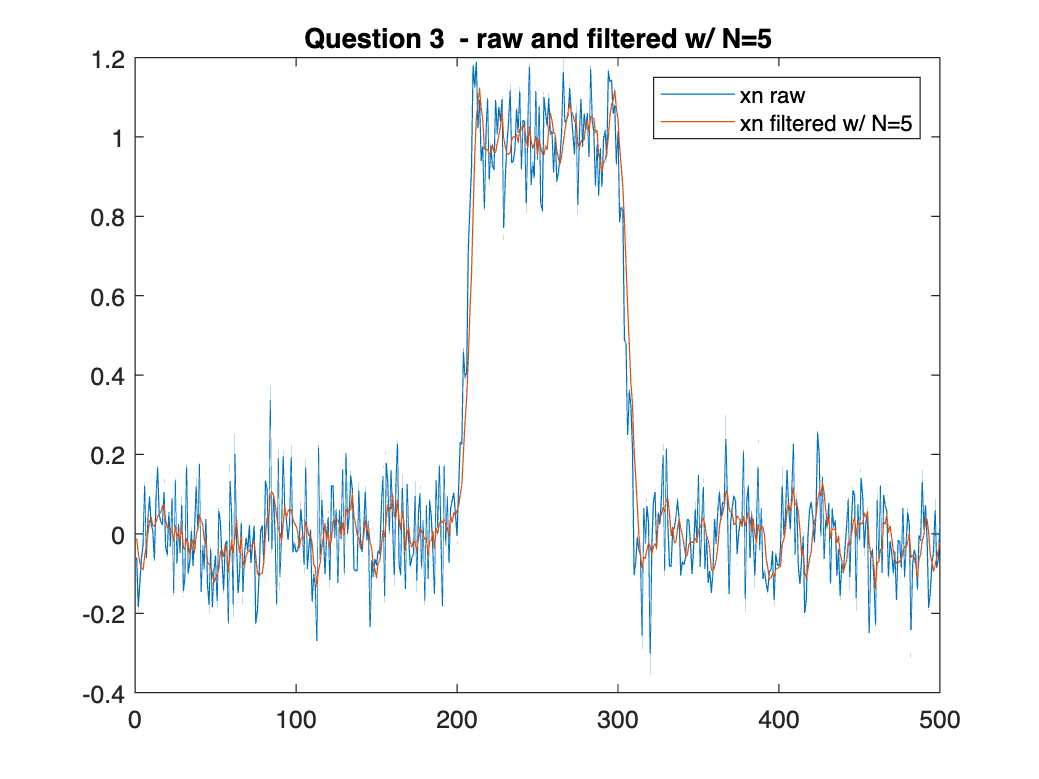

f7 = figure("Name","Question 3  - raw and filtered w/ N=5");
plot(xn);
hold on;

N = 5;
B = 1/N*ones(N, 1);
xn_avg5 = filter(B, 1, xn);
plot(xn_avg5);
title("Question 3  - raw and filtered w/ N=5");
legend('xn raw','xn filtered w/ N=5');

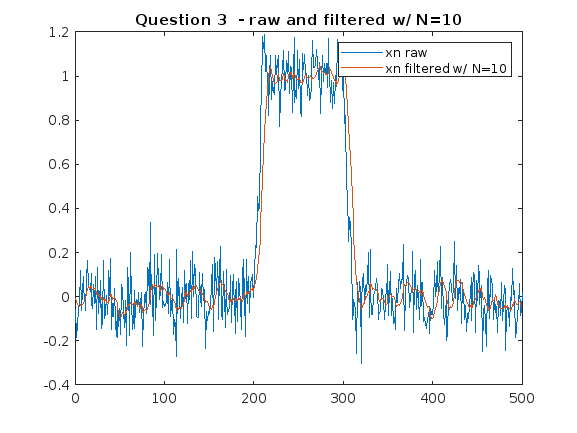

% --------------------------------
f8 = figure("Name","Question 3  - raw and filtered w/ N=10");
plot(xn);
hold on;

N = 10;
B = 1/N * ones(N, 1);
xn_avg10 = filter(B, 1, xn);
plot(xn_avg10);
title("Question 3  - raw and filtered w/ N=10");
legend('xn raw','xn filtered w/ N=10');

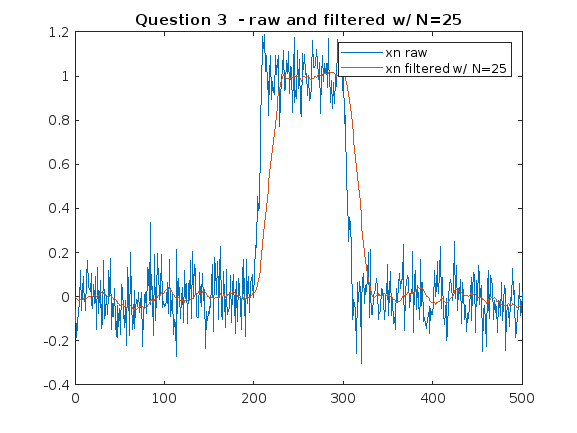

% --------------------------------
f9 = figure("Name","Question 3  - raw and filtered w/ N=25");
plot(xn);
hold on;

N = 25;
B = 1/N * ones(N, 1);
xn_avg25 = filter(B, 1, xn);
plot(xn_avg25);
title("Question 3  - raw and filtered w/ N=25");
legend('xn raw','xn filtered w/ N=25');

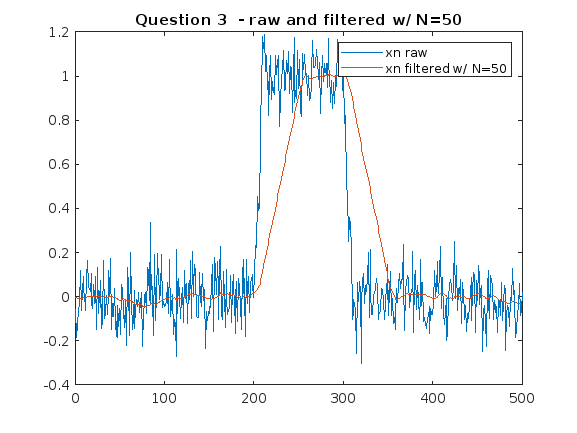

% --------------------------------
f10 = figure("Name","Question 3  - raw and filtered w/ N=50");
plot(xn);
hold on;

N = 50;
B = 1/N * ones(N,1);
xn_avg50 = filter(B,1,xn);
plot(xn_avg50);
title("Question 3  - raw and filtered w/ N=50");
legend('xn raw','xn filtered w/ N=50');
hold off;

	Comment(s): After ploting raw xn vs. filter xn for various N (5, 10, 25, 50) shown, we get a smoothing effect as expected but we also observe that the plot of the filtered xn appears as if the it is delayed by amount N. This is because N number of data points of raw xn have to plotted before the first data point of filtered xn is plotted, effective delaying the filtered xn plot by N amount.

	The size of N should be tailored to the data set. N=5 results in an almost as noisy graph and N=50 results in over-smoothing of the raw data. Subjectively a value of N=10 or N=25 results in the best output that removes a large amount of noise while preserving a reasonabily accurate repersentation of the data.

#### **Question 4:**

The signal x[n] is a DT, even periodic square wave w/ $N=32$ & $N_1 =4$...

a) Compute Fouier series coefficients for x[n]...

b) Now using Fourier series of coefficients...

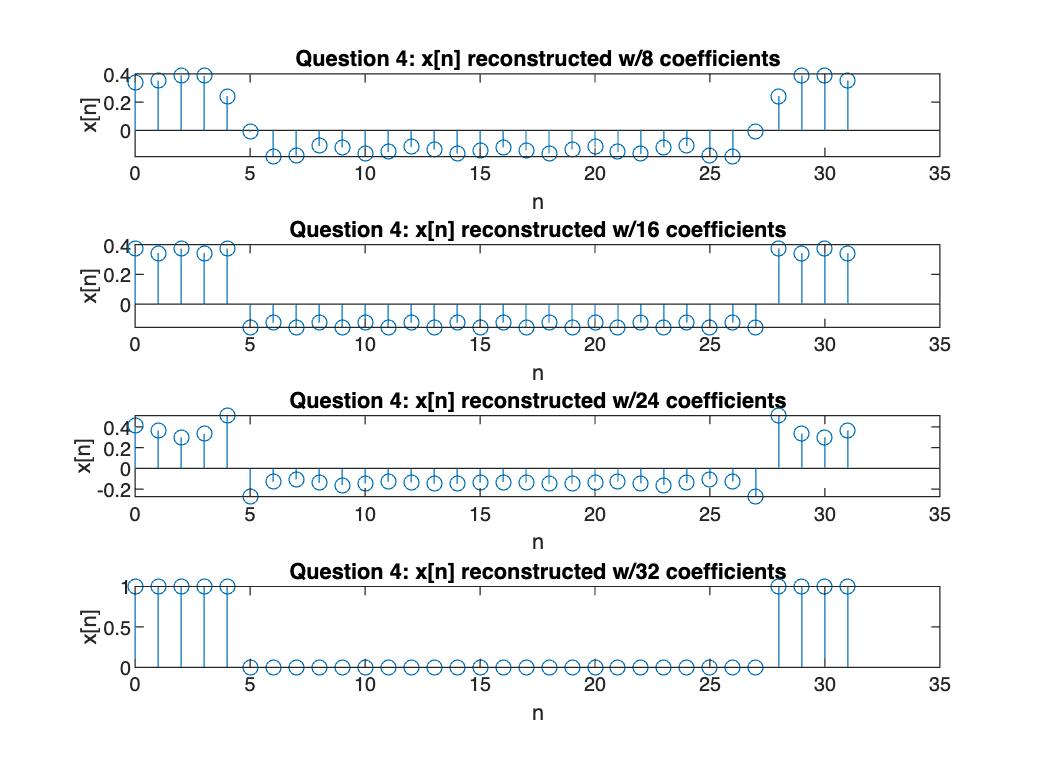

N = 32;
n1 = 0:1:31;
t=0:1:N-1;
sq_wave=heaviside(-(t-4))+heaviside(t-(N-9/2));
x = zeros(1,32);
for i = 1:N
	if sq_wave(i) > 0
		sq_wave(i) = 1;
    else
		sq_wave(i) = 0;
	end
end

a_k = zeros(1,N);
 
for k = 1:N
    for n = 1:N
        a_k(k) = a_k(k)+sq_wave(n)*exp(-j*k*(2*pi/N)*n);
    end
end
 
a_k = a_k*(1/N);
 
for n = 1:N
	for k = 1:N/4
		x(n) = x(n) + a_k(k)*exp(j*k*(2*pi()/N)*n);
	end
end
 
f10 = figure("Name","Question 4: x[n] reconstructed w/8 Coefficients");
subplot(4,1,1)
stem(n1, real(x))
xlabel("n")
ylabel("x[n]")
title("Question 4: x[n] reconstructed w/8 coefficients")
 
x = zeros(1,32);
 
for n = 1:N
	for k = 1:N/2
		x(n) = x(n) + a_k(k)*exp(j*k*(2*pi()/N)*n);
	end
end
 
subplot(4,1,2)
stem(n1, real(x))
xlabel("n")
ylabel("x[n]")
title("Question 4: x[n] reconstructed w/16 coefficients")
x = zeros(1,32);

for n = 1:N
	for k = 1:N*3/4
		x(n) = x(n) + a_k(k)*exp(j*k*(2*pi()/N)*n);
	end
end

subplot(4,1,3)
stem(n1, real(x))
xlabel("n")
ylabel("x[n]")
title("Question 4: x[n] reconstructed w/24 coefficients")
x = zeros(1,32);
 
for n = 1:N
	for k = 1:N
		x(n) = x(n) + a_k(k)*exp(j*k*(2*pi()/N)*n);
	end
end

subplot(4,1,4)
stem(n1, real(x))
xlabel("n")
ylabel("x[n]")
title("Question 4: x[n] reconstructed w/32 coefficients")

    Inspecting the plot above we can observe the signal has been reconstructed with 32 harmonic frequencies.